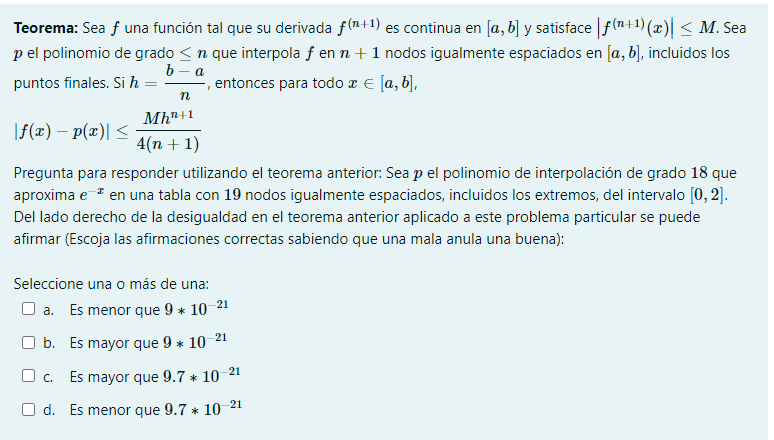

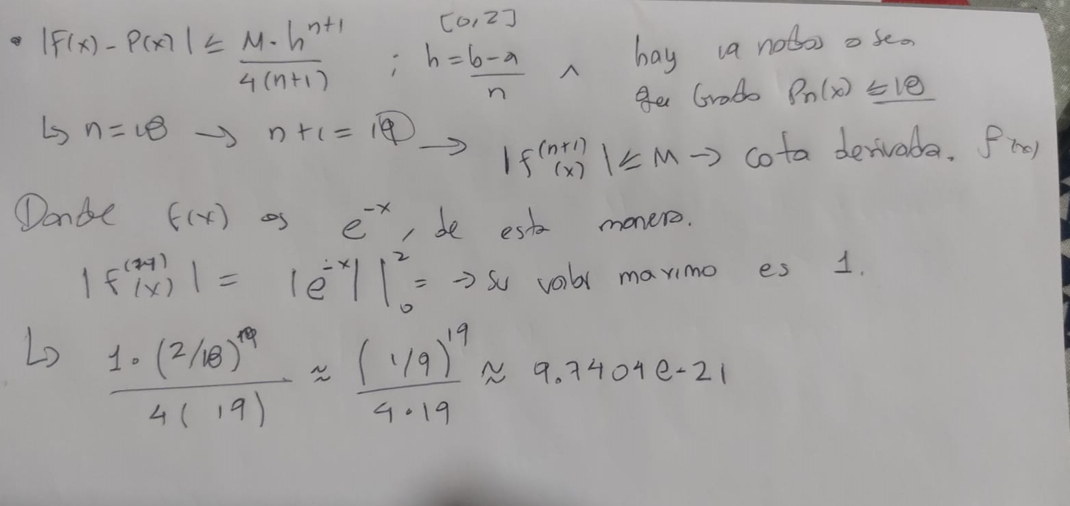

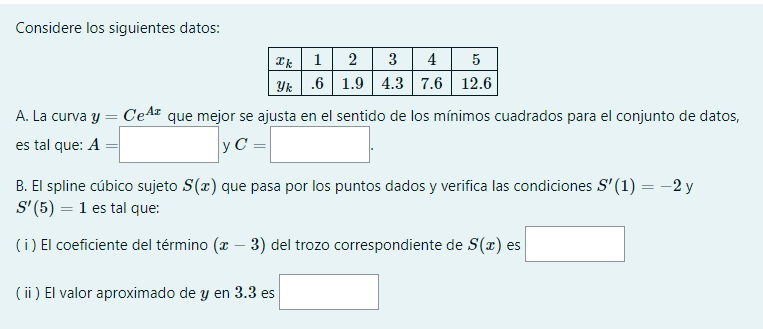

x = [1 2 3 4 5]

x =      1     2     3     4     5


y = [0.6 1.9 4.3 7.6 12.6]

y =     0.6000    1.9000    4.3000    7.6000   12.6000


Y = log(y)

Y =    -0.5108    0.6419    1.4586    2.0281    2.5337


[A, B] = lsline0 (x,Y)

A = 0.7475

B = -1.0123

c = exp(B) %deberia ser 0.3634 y es correcto

c = 0.3634

A

A = 0.7475

% A deberia ser 0.7475

%S = csfit (X, Y, dx0, dxn) dx0 es derivada en x0 y en xn
S = csfit (x, y, -2, 1)

S =    -1.8857    5.1857   -2.0000    0.6000
    0.1571   -0.4714    2.7143    1.9000
    1.0571   -0.0000    2.2429    4.3000
   -3.5857    3.1714    5.4143    7.6000


polyval(S(3,:),(3.3-3))

ans = 5.0014

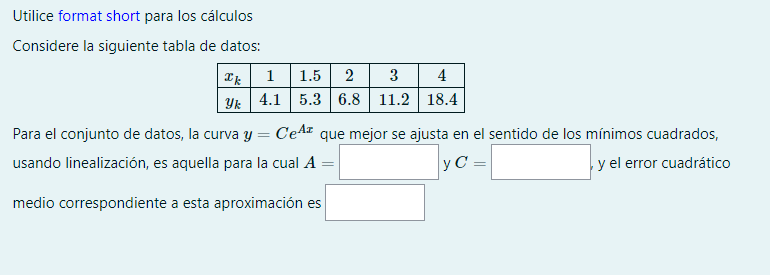

format short 
x = [1 1.5 2 3 4]

x =     1.0000    1.5000    2.0000    3.0000    4.0000


y = [4.1 5.3 6.8 11.2 18.4]

y =     4.1000    5.3000    6.8000   11.2000   18.4000


Y = log(y)

Y =     1.4110    1.6677    1.9169    2.4159    2.9124


[A, B] = lsline0 (x, Y)

A = 0.4998

B = 0.9153

c = exp(B) %deberia ser 2.4976 y es correcto

c = 2.4976

A

A = 0.4998

% A deberia ser 0.4998


%Modelo 
y1= c*exp(A*x)

y1 =     4.1168    5.2855    6.7859   11.1854   18.4372


%Error cuadratico medio:

%error_cuad_medio = sqrt(1/m*sum((f(x)-y))^2) 

% m = Numero de nodos, para este ejemplo, 5 nodos

ee = sqrt(1/5*sum((exp(polyval([A B],x)-y)).^2))%Cuando piden ERROR CUADRATICO MEDIO 

ee = 0.0329

% es lo mismo Pero dividido la cantidad de datos

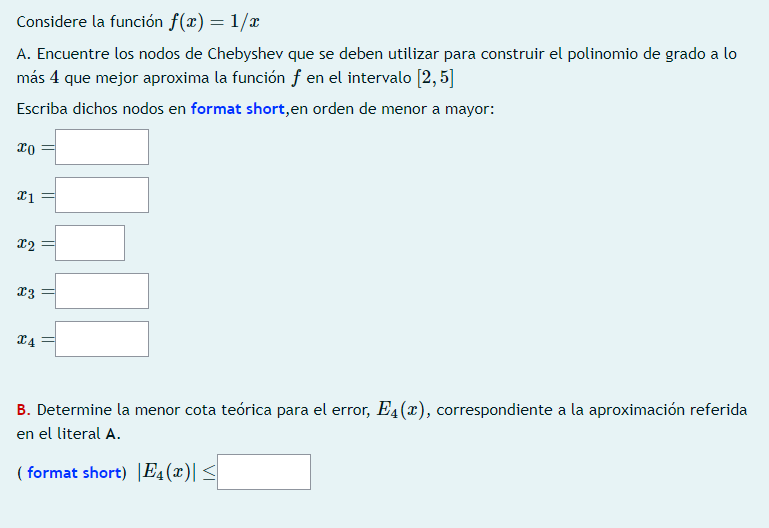

format short
clear all
f = @(x) 1./x

f = function_handle with value:
    @(x)1./x


a= 2

a = 2

b=5

b = 5

[C, X, Y] = cheby (f, 4, a, b);

X %Estos son los nodos de chebychev

X =     4.9266    4.3817    3.5000    2.6183    2.0734


%COTA TEÓRICA
%%numero de derivada n +1, donde n es el grado del polinomio
syms x
f = @(x) 1./x; 
a = 2; 
b =5; 
n = 4;
derivada=abs(diff(f(x),x,(n+1)))

$$derivada = \frac{120}{{\left|x\right|}^{6}}$$

der=matlabFunction(derivada)

der = function_handle with value:
    @(x)1.0./abs(x).^6.*1.2e+2


X=linspace(a,b,10000)

X =     2.0000    2.0003    2.0006    2.0009    2.0012    2.0015    2.0018    2.0021    2.0024    2.0027    2.0030    2.0033    2.0036    2.0039    2.0042    2.0045    2.0048    2.0051    2.0054    2.0057    2.0060    2.0063    2.0066    2.0069    2.0072    2.0075    2.0078    2.0081    2.0084    2.0087    2.0090    2.0093    2.0096    2.0099    2.0102    2.0105    2.0108    2.0111    2.0114    2.0117    2.0120    2.0123    2.0126    2.0129    2.0132    2.0135    2.0138    2.0141    2.0144    2.0147


cota_1=max(der(X))

cota_1 = 1.8750

cota=(2.*((b-a).^(n+1)))./((4.^(n+1)).*factorial(n+1))

cota = 0.0040

cotatotal=cota_1.*cota

cotatotal = 0.0074


%Rta es cotatotal

%%CON ESTO SE CALCULA LA COTA TEORICA